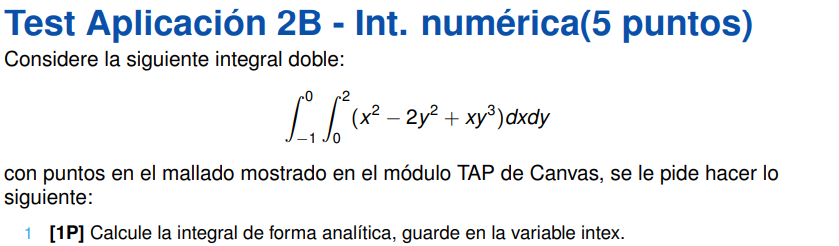

syms x y
f= @(x,y) (x^2-2*y^2+x*y^3 )

f = function_handle with value:
    @(x,y)(x^2-2*y^2+x*y^3)


I1 = int(f, x,0,2);
I2 = int(I1,y,-1,1);
intex = double(I2)

intex =    2.666666666666667


op=1

op =      1


syms x y

x1=0;
x2=2;
y1=-1;
y2=1;
h=0.2;

f1 = @(x) (x.^2-2*y.^2+x*y^3 );

tmp = simp(f1,x1,x2,h);
I1=matlabFunction(tmp);




Itotal = simp(I1,y1,y2,h);

isimpcomp=Itotal

isimpcomp =    2.666666666666666


n=4;
syms p q
fx = @(x,y) (x^2-2*y^2+x*y^3 )

fx = function_handle with value:
    @(x,y)(x^2-2*y^2+x*y^3)



x1=0;
x2=2;
y1=-1;
y2=1;

intgauss= gaussnp(fx,x1,x2,y1,y2,4)

fy = function_handle with value:
    @(y)y.^2.*(-4.000000000000001)+y.^3.*2.0+2.666666666666667


g = function_handle with value:
    @(t)t.^2.*-4.0+t.^3.*2.0+8.0./3.0


intgauss =    2.666666666666667


err_rel_simpson = abs(isimpcomp-intex)/abs(intex)

err_rel_simpson =      1.665334536937735e-16


err_rel_gauss = abs(intex-intgauss)/abs(intex)

err_rel_gauss =      0




esc=0

esc =      0


function I = simp(f, a,b,h)

X = [a:h:b];
n = length(X)-1;
Y = f(X);

i_impar = [1:2:n-1]+1;
i_par = [2:2:n-2]+1;

I = (h/3)*( Y(1) + 4*sum(Y(i_impar) ) + 2*sum(Y(i_par) ) + Y(end) );

end

function I = simp2(f, a, b, h)

I = (3*h/8)*(  f(a)+ 3*f(a+h)+3*f(a+2*h) + f(b));

end


function If=gaussnp(f,a,b,c,d,n)
%Aporte de alumnos del ciclo 2022-2 del curso de metodos numericos
syms x
%PRIMER PASO: Calcular el polinomio de Legendre de grado n
lg=legendreP(n,x);
dlg=matlabFunction(diff(lg,x));
%SEGUNDO PASO: Calcular las raíces del polinomio de Legendre
roots=double(vpasolve(lg==0));
%TERCER PASO: Calcular los pesos de las raíces del polinomio de Legendre
pesos=(2./((1-roots.^2).*dlg(roots).^2));
%CUARTO PASO: Transformar los límites de la fxn
syms t y
x=((b-a)*t+(a+b))/2;
F=matlabFunction(f(x,y));
Ix=((b-a)/2)*sum(pesos.*(F(roots,y)));
fy = matlabFunction(Ix)
y=((d-c)*t+(c+d))/2;
g =matlabFunction(fy(y))
If = ((d-c)/2)*sum(pesos.*(g(roots)));
end